# Exercise 2

clc
close all
clear

P0 = 120; aP = 3e-4; aN = 7e-4;

P = @(q) P0-aP*q.^2;
N = @(q) aN*q.^2;

q = linspace(0,500);
plot(q,P(q),q,N(q))
q_eq = fsolve(@(q) P(q)-N(q),300)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


q_eq = 346.4102

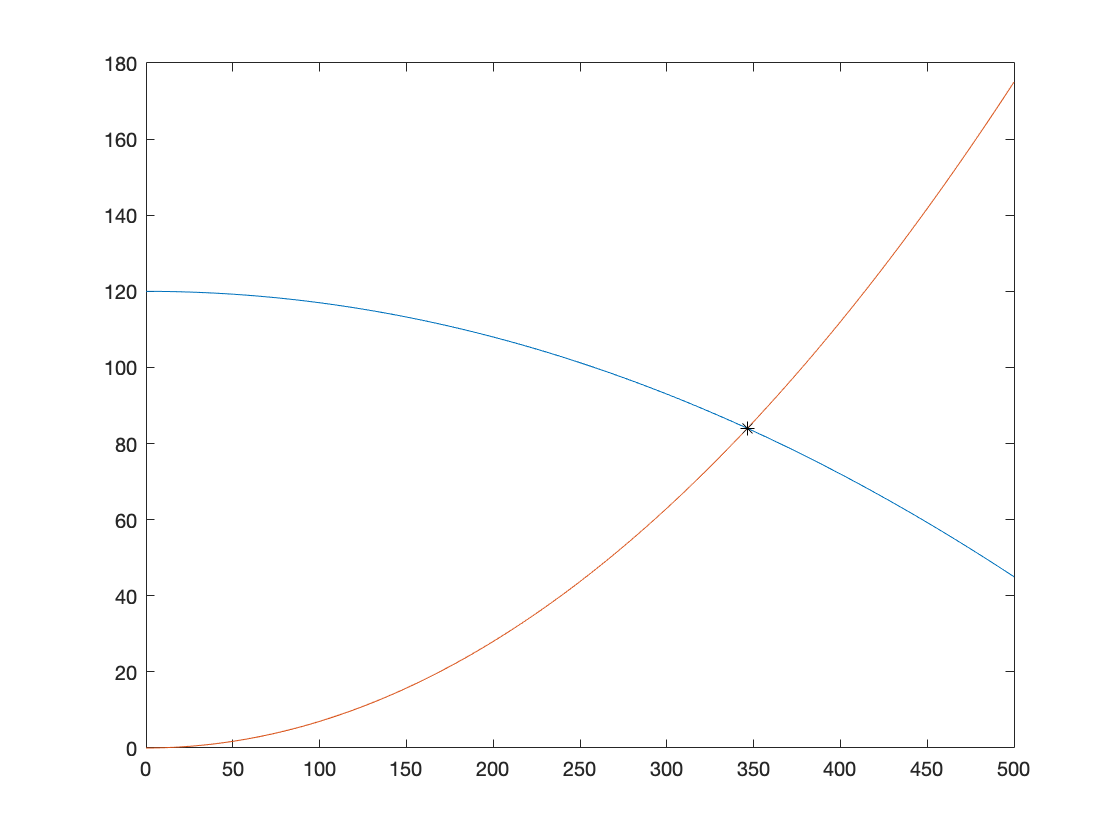

hold on
plot(q_eq,P(q_eq),'*k')
hold off

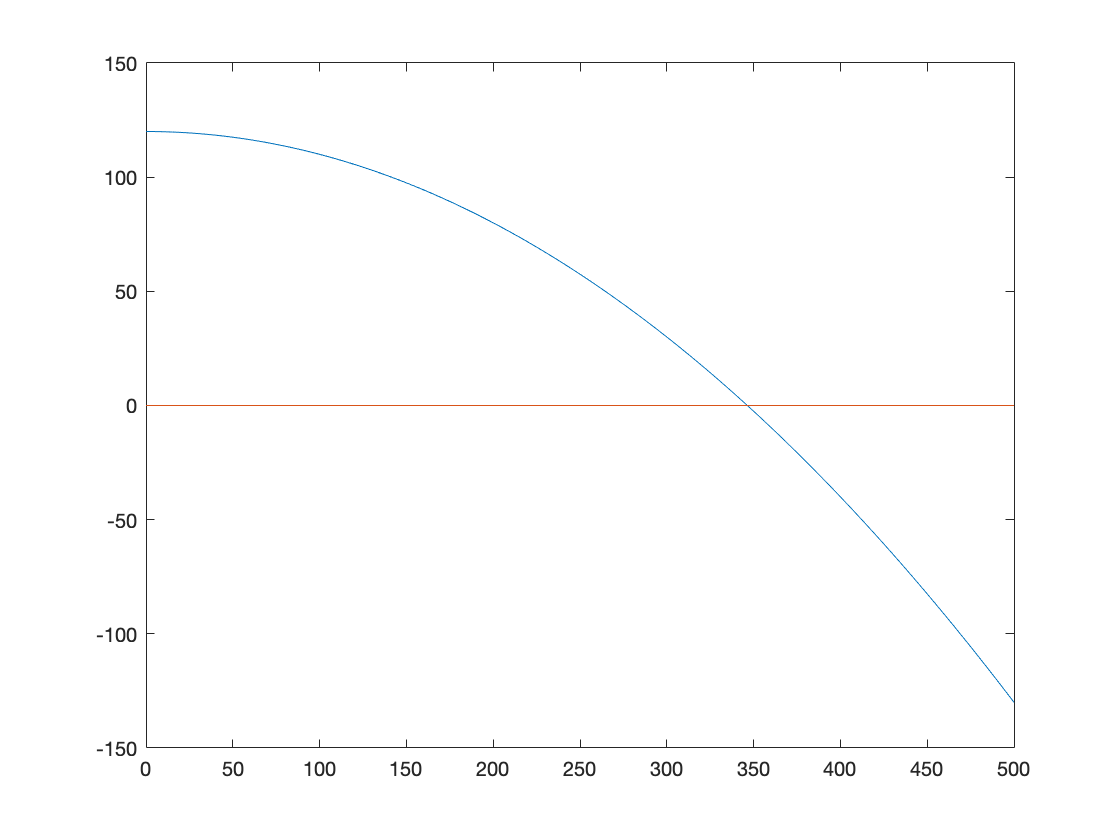

plot(q,P(q)-N(q),[q(1) q(end)],[0 0])

## Exercise 4

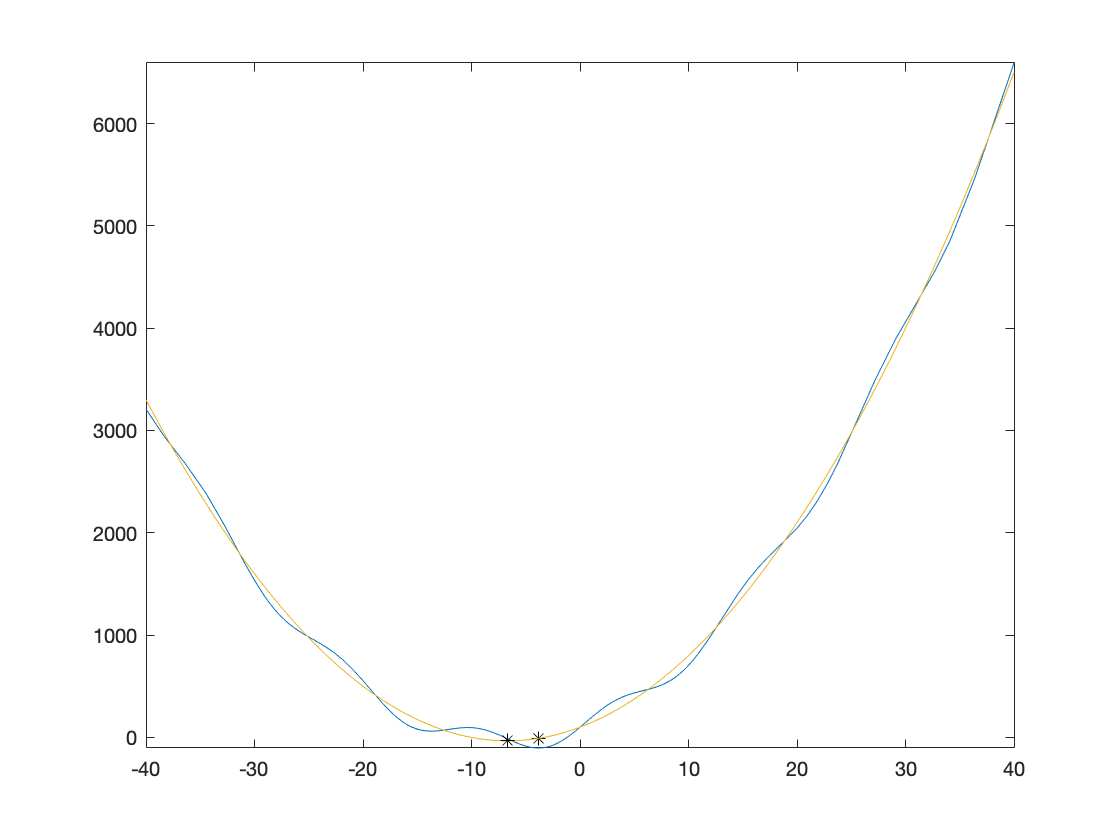

a = 3; b = 40; c = 100;
f = @(x) a*x.^2+b*x+c;

x = linspace(-40,40);
plot(x,f(x))

xmin = fminsearch(f,0);
hold on
plot(xmin,f(xmin),'*k')

g = @(x) f(x)+c*sin(x/2);

hold off

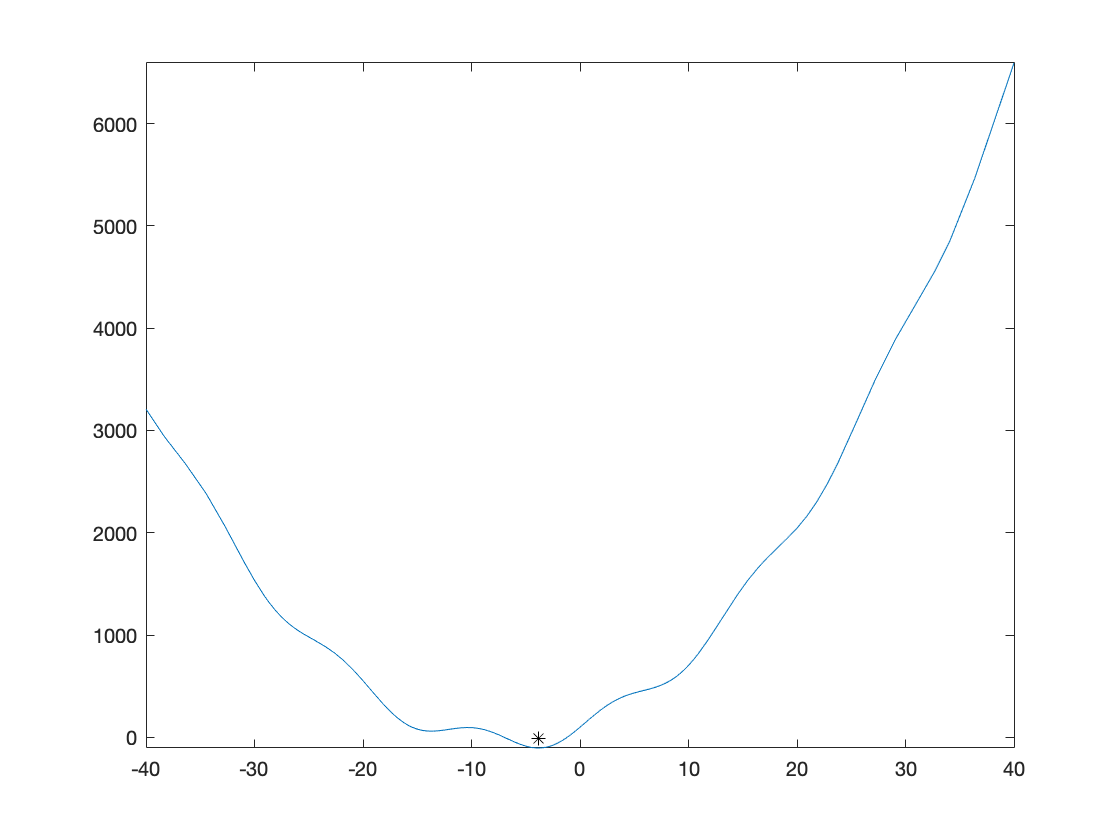

fplot(g,[-40 40])
xmin = fminsearch(g,0);
hold on
plot(xmin,f(xmin),'*k')